# FitHelicalMotion

Fits a parametric vector path to helical motion described by the time-dependent vector

Author: Max Vogel

Define Constants

clear;
R = 1; % m
omega = .33 * pi; % Hz
vz = 1; % m/s

Set up time

ntimes=10;
t=[0:.1:ntimes]';% times col vector
ndata=length(t);

Set initial values

R0=[R,R]; % initial position row vector
omega_0=[omega,omega]; % initial velocity row vector
vz0=[vz]; % initial acceleration row vector
beta0=[R0'; omega_0'; vz0'];% parameter initial values

Create helical motion equations in each axis

x = R*cos(omega*t)+rand(ndata,1)/5;
y = R*sin(omega*t)+rand(ndata,1)/5;
z = vz * t+rand(ndata,1)/5;

Generate combined vectors

xt=[x;y;z]; % path reshaped into one long column vector
tt=[t;t;t];% corresponding long column vector of times
ct1=[ones(ndata,1);zeros(ndata,1);zeros(ndata,1)];% coordinate logical
ct2=[zeros(ndata,1);ones(ndata,1);zeros(ndata,1)];% coordinate logical
ct3=[zeros(ndata,1);zeros(ndata,1);ones(ndata,1)];% coordinate logical
tbl=table(ct1,ct2,ct3,tt,xt);% columns are coordinate logicals, predictor time, and value

Create a model function for our motion

modelfun = @(b,a)( ...
a(:,1).*(b(1)*cos(b(2) * a(:,4)))+...
a(:,2).*(b(3)*sin(b(4) * a(:,4)))+...
a(:,3).*(b(5) * a(:,4))...
);

Create a fit and grab the equations in each axis

model = fitnlm(tbl, modelfun, beta0)

model = Nonlinear regression model:
    xt ~ (ct1*(b1*cos(b2*tt)) + ct2*(b3*sin(b4*tt)) + ct3*(b5*tt))

Estimated Coefficients:
          Estimate       SE        tStat       pValue   
          ________    _________    ______    ___________

    b1    0.99188      0.013958    71.064    6.8184e-189
    b2     1.0316     0.0026761     385.5              0
    b3     1.0341      0.014684    70.425    8.6601e-188
    b4     1.0306     0.0022442    459.23              0
    b5      1.015      0.001747    581.02              0


Number of observations: 303, Error degrees of freedom: 298
Root Mean Squared Error: 0.102
R-Squared: 0.999,  Adjusted R-Squared 0.999
F-statistic vs. zero model: 6.95e+04, p-value = 0

bfit  = model.Coefficients.Estimate;
xfit = [  bfit(1)*cos(bfit(2) * t) ];
yfit = [  bfit(3)*sin(bfit(4) * t) ];
zfit = [  bfit(5)*t ];
xdat = x; ydat = y; zdat = z;

Plot the observations and fit in 3D

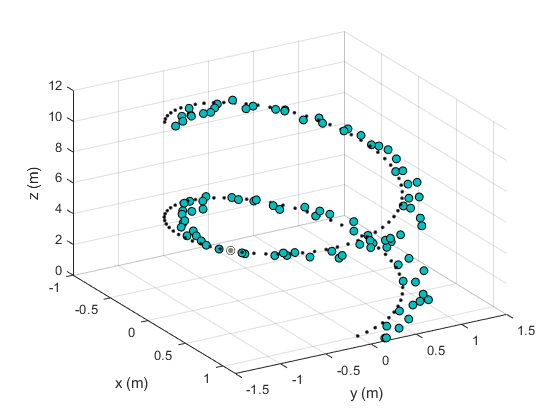

scatter3(xdat,ydat,zdat,'MarkerEdgeColor','k','MarkerFaceColor',[0 .75 .75])
hold on;
scatter3(xfit,yfit,zfit,'.','MarkerEdgeColor','k','MarkerFaceColor',[0 .75 .75])
xlabel('x (m)');ylabel('y (m)');zlabel('z (m)');
view(-30,10)
view([59 32])